% Setup
format compact
clearvars
clc

% Variables
SampleList = ["NoiseArduino50V.mat", "NoiseArduino25V.mat", "NoiseArduino0V.mat", "NoiseArduinoN50V.mat", "NoiseArduinoN25V.mat", "NoiseArduinoPSUoff.mat"];

Fs = 6000/30; % Sampling Freq

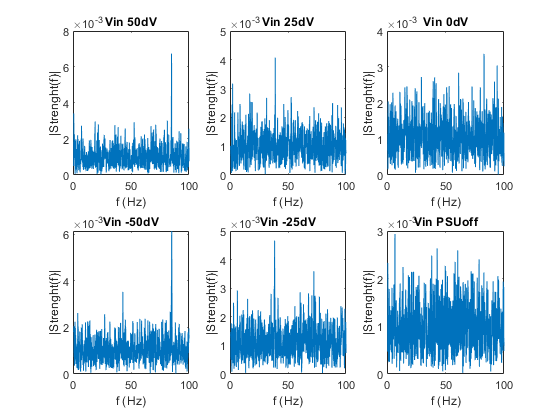

Top 3 frequencies: 84.4 0.1 84.3
Top 3 frequencies: 38.5 1.7 16.5
Top 3 frequencies: 82.4 93.6 60.7
Top 3 frequencies: 84.6 84.7 84.4
Top 3 frequencies: 37.9 71.8 37.8
Top 3 frequencies: 6.3 42.3 59.9


% Fourier
figure();
for i = 1:length(SampleList)
    YData = load(join(['./Data/', SampleList(i)], ''));
    YData = YData.simout(500:end,2); % Estacionari a partir de la mostra 500
    L = length(YData);
    Y = fft(YData);
    P2 = abs(Y/L);
    P1 = P2(1:(fix(L/2)+1));
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    [~,max3freqInd]=maxk(P1(5:end),3);
    fprintf('Top 3 frequencies: %.1f %.1f %.1f\n', f(max3freqInd))
    subplot(2, 3, i);
    plot(f(5:end), P1(5:end)); % Supressed f<<
    title(join(['Vin ', strrep(strrep(extractBetween(SampleList(i), 'Arduino', '.mat'), 'N', '-'), 'V', 'dV')], ''));
    xlabel('f (Hz)');
    ylabel('|Strenght(f)|');
end